1

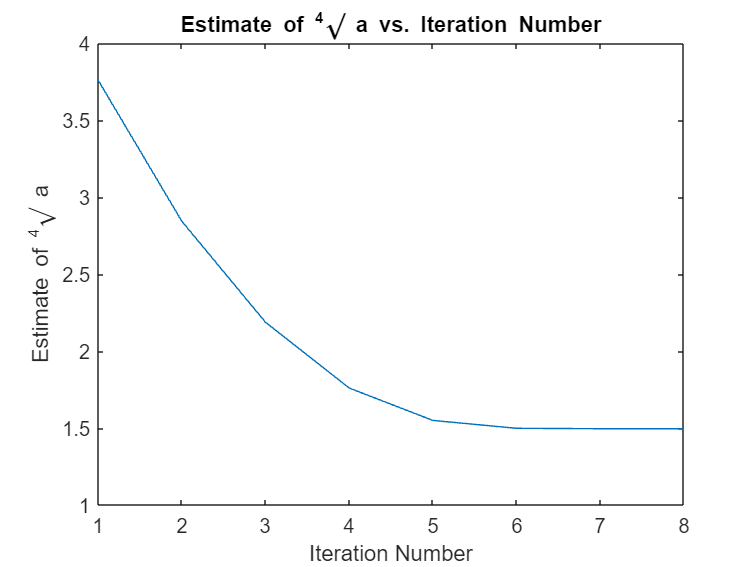

% Newton-Raphson method to find the fourth root of 5
% a
clearvars;
a = 5;
x0 = a;
f = @(x) x^4 - a;
df = @(x) 4 * x^3;
threshold = 1e-8; 
max_iter = 100;

x = x0;
iter = 0;

while abs(f(x)) > threshold && iter < max_iter
    x = x - f(x) / df(x);
    iter = iter + 1;
    roots(iter) = x;
end

figure;
plot(1:iter, roots);
title('Estimate of ^4\surd a vs. Iteration Number');
xlabel('Iteration Number');
ylabel('Estimate of ^4\surd a');



fprintf('Iterations required for convergence: %d\n', iter);

Iterations required for convergence: 8


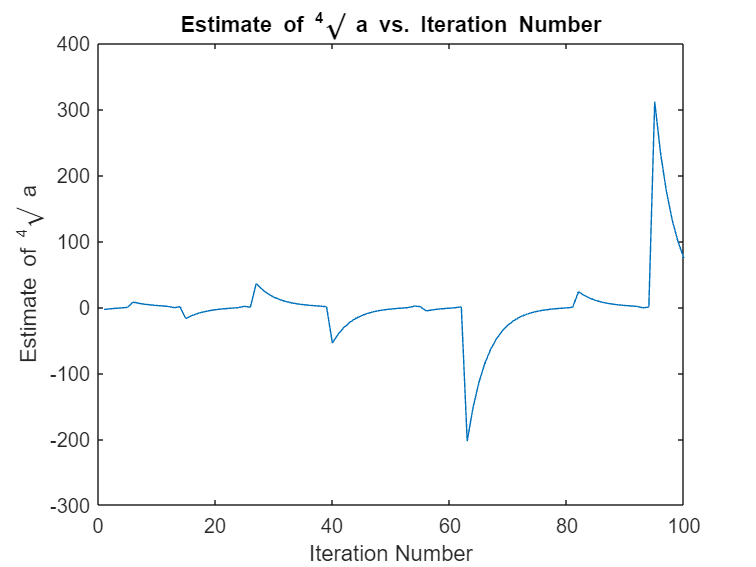

% b
clearvars;
a = -5;
x0 = a;
f = @(x) x^4 - a;
df = @(x) 4 * x^3;
threshold = 1e-8; 
max_iter = 100;

x = x0;
iter = 0;

while abs(f(x)) > threshold && iter < max_iter
    x = x - f(x) / df(x);
    iter = iter + 1;
    roots(iter) = x;
end

figure;
plot(1:iter, roots);
title('Estimate of ^4\surd a vs. Iteration Number');
xlabel('Iteration Number');
ylabel('Estimate of ^4\surd a');



fprintf('Iterations required for convergence: %d\n', iter);

Iterations required for convergence: 100


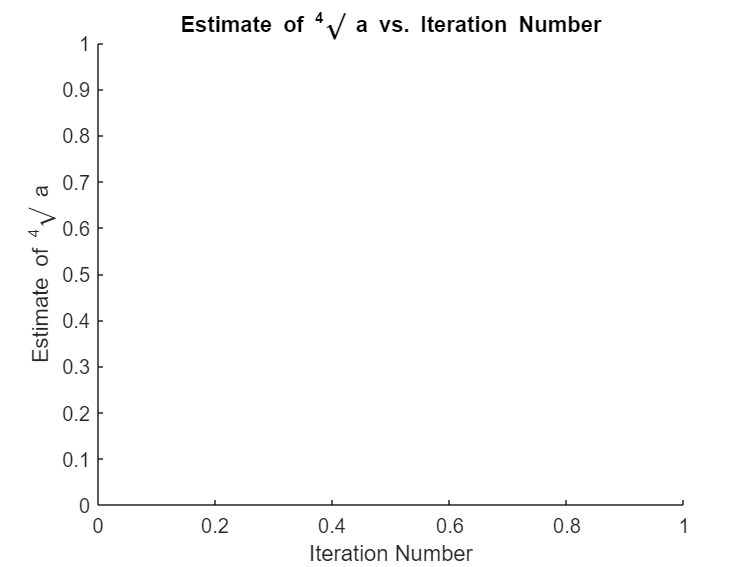

% c
clearvars;
a = 0;
x0 = a;
f = @(x) x^4 - a;
df = @(x) 4 * x^3;
threshold = 1e-8; 
max_iter = 100;

x = x0;
iter = 0;

while abs(f(x)) > threshold && iter < max_iter
    x = x - f(x) / df(x);
    iter = iter + 1;
    roots(iter) = x;
end

figure;
%plot(1:iter, roots);
title('Estimate of ^4\surd a vs. Iteration Number');
xlabel('Iteration Number');
ylabel('Estimate of ^4\surd a');



fprintf('Iterations required for convergence: %d\n', iter);

Iterations required for convergence: 0


The process fails if you start at 𝑥0 = 0 because the derivative at that point becomes zero, causing a division by zero error in the Newton-Raphson update formula. This violates one of the assumptions of the Newton-Raphson method, which requires non-zero derivatives.

2

a) Given the limitations of the microprocessor and time constraints, the best method to find zero crossings would likely be the Bisection method. This method is simple and doesn't require derivatives, making it suitable for this scenario.

**Look at bottom for 2b**

% c
signal_freq = 1; % in Hz
sampling_freq = 1000; % Assuming 1000 samples per second
period = 1 / signal_freq;
bracket_width = period / 10;

lower_bound = 0;
upper_bound = lower_bound + bracket_width;

threshold = 1e-8;
%zero_crossing_ans = zero_crossing_bisection(lower_bound, upper_bound, threshold);

%disp('Zero crossing:');
%disp(zero_crossing_ans);

c) Since the signal is approximately sinusoidal with a frequency around 1 Hz, the period of the signal can be estimated and used to initialize the brackets for the Bisection method. For example, if the sampling frequency is known, you can estimate the period and set the initial brackets accordingly.

3

7**[3, -1; 4, 2] - 2*[0, -1; -3, 2] + 1*[0, 3; -3, 4] =*

*7*(6-(-4))-2*(0-(3))+1*(0-(-9)) =*

*7*10-2*(-3)+1*9 =*

*85*

A = [7, 2, 1; 0, 3, -1; -3, 4, 2];
disp(det(A));

    85



2b

function zero_crossing = zero_crossing_bisection(a, b, threshold) %2b
    while (b - a) > threshold
        midpoint = (a + b) / 2;
        if f(midpoint) == 0
            zero_crossing = midpoint;
            return;
        elseif f(a) * f(midpoint) < 0
            b = midpoint;
        else
            a = midpoint;
        end
    end
    zero_crossing = (a + b) / 2;
end